%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%
% Competition model (rabbits vs sheep / competing species):
%   x' = x(3 - x - 2y)
%   y' = y(2 - x - y)
%
% Goals:
%   - phase plane in the first quadrant
%   - nullclines (lines) + trajectories
%   - equilibria and local linearization (Jacobian eigenvalues)
%
% Fixed points:
%   (0,0), (3,0), (0,2), (1,1)
% with (1,1) a saddle (det<0).
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

clear; close all; clc;

f = @(t,z) [ z(1)*(3 - z(1) - 2*z(2));
             z(2)*(2 - z(1) - z(2)) ];

% Jacobian:
% f1 = 3x - x^2 - 2xy -> fx = 3 - 2x - 2y, fy = -2x
% f2 = 2y - xy - y^2  -> gx = -y, gy = 2 - x - 2y
J = @(x,y) [ 3 - 2*x - 2*y,  -2*x;
             -y,             2 - x - 2*y ];

eq = [0 0; 3 0; 0 2; 1 1];

fprintf('Equilibria and eigenvalues:\n');

Equilibria and eigenvalues:


for i=1:size(eq,1)
    x=eq(i,1); y=eq(i,2);
    A = J(x,y);
    lam = eig(A);
    fprintf('  (%.1f, %.1f): eig = (%.3f, %.3f)\n', x,y, lam(1), lam(2));
end

  (0.0, 0.0): eig = (2.000, 3.000)
  (3.0, 0.0): eig = (-3.000, -1.000)
  (0.0, 2.0): eig = (-2.000, -1.000)
  (1.0, 1.0): eig = (0.414, -2.414)


fprintf('\nExpected: (0,0) unstable; (3,0) stable node; (0,2) stable node; (1,1) saddle.\n\n');


Expected: (0,0) unstable; (3,0) stable node; (0,2) stable node; (1,1) saddle.



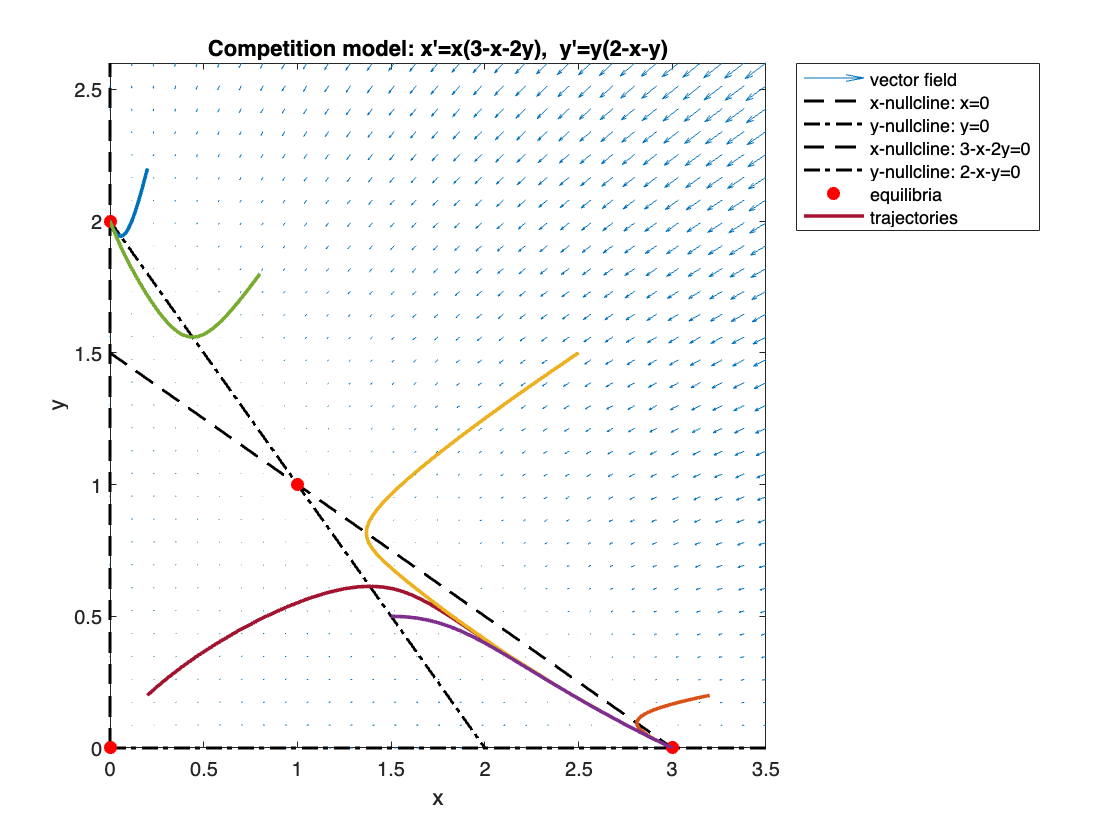


% Plot window (focus on first quadrant)
xlimv = [0 3.5];
ylimv = [0 2.6];

% Vector field grid
[xg,yg] = meshgrid(linspace(xlimv(1),xlimv(2),31), linspace(ylimv(1),ylimv(2),31));
ug = xg.*(3 - xg - 2*yg);
vg = yg.*(2 - xg - yg);

figure('Color','w','Name','Example 3: Competition model');
hold on; box on;
quiver(xg,yg,ug,vg,'AutoScale','on');
xlabel('x'); ylabel('y');
title('Competition model: x''=x(3-x-2y),  y''=y(2-x-y)');

% Nullclines:
% x-nullclines: x=0 and 3 - x - 2y = 0 => y=(3-x)/2
% y-nullclines: y=0 and 2 - x - y = 0 => y=2-x
plot([0 0],[ylimv(1) ylimv(2)],'k--','LineWidth',1.4);     % x=0
plot([xlimv(1) xlimv(2)],[0 0],'k-.','LineWidth',1.4);     % y=0
xx = linspace(xlimv(1),xlimv(2),400);
plot(xx, (3-xx)/2, 'k--','LineWidth',1.4);                 % x-nullcline line
plot(xx, 2-xx, 'k-.','LineWidth',1.4);                     % y-nullcline line

% mark equilibria
plot(eq(:,1),eq(:,2),'ro','MarkerFaceColor','r','MarkerSize',6);

% Trajectories from different initial conditions
tspan = [0 15];
ICs = [0.2 0.2;
       0.2 2.2;
       3.2 0.2;
       2.5 1.5;
       1.5 0.5;
       0.8 1.8];

for k=1:size(ICs,1)
    z0 = ICs(k,:)';
    [t,z] = ode45(f,tspan,z0);
    plot(z(:,1),z(:,2),'LineWidth',1.8);
end

xlim(xlimv); ylim(ylimv);
legend({'vector field','x-nullcline: x=0','y-nullcline: y=0',...
        'x-nullcline: 3-x-2y=0','y-nullcline: 2-x-y=0',...
        'equilibria','trajectories'}, 'Location','bestoutside');